load googlenet_2.mat
signds = imageDatastore("D:\college\FYP\Experimenting\test\no-parking","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.8,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224],signTrain);
resizeTestImgs = augmentedImageDatastore([224 224],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",5,"VerboseFrequency",2);

% Training the network
[noParkingNetwork,info] = trainNetwork(resizeTrainImgs,googlenet_2,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:24 |       51.00% |       1.0528 |          0.0010 |
|       2 |           2 |       00:00:45 |       60.00% |       0.9424 |          0.0010 |
|       4 |           4 |       00:01:36 |       74.00% |       0.5213 |          0.0010 |
|       5 |           5 |       00:02:06 |       81.00% |       0.4989 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


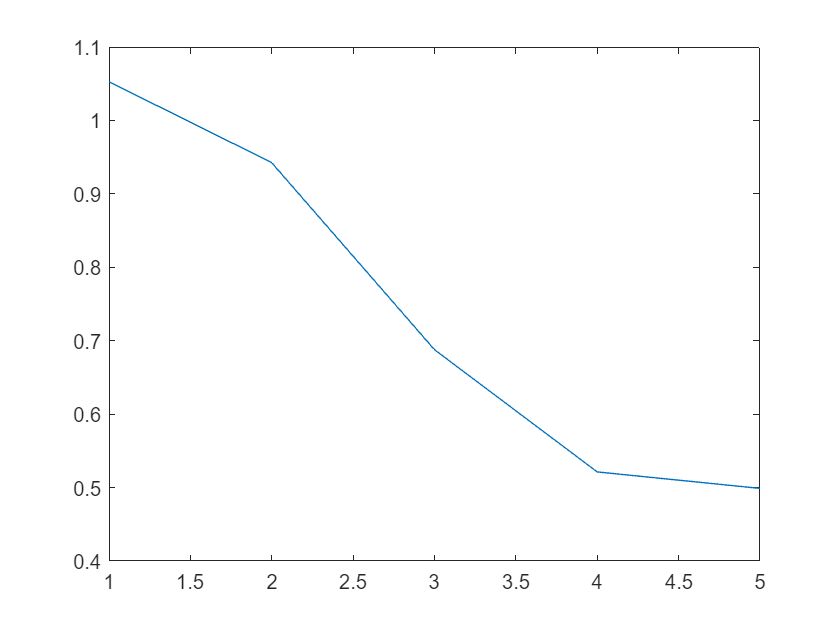


% Evaluating Performance
plot(info.TrainingLoss);

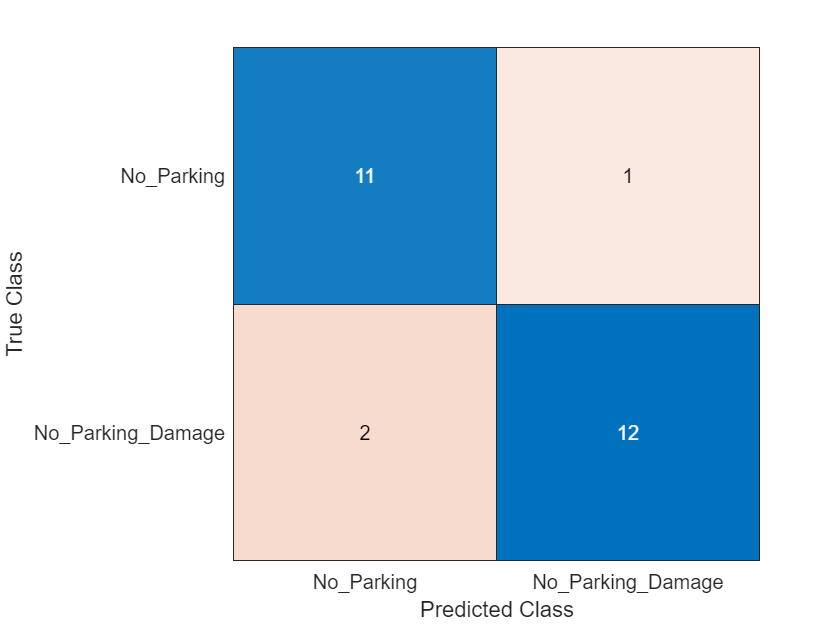



% Prediction
signPrediction = classify(noParkingNetwork,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);